# LAB 2: FREQUENCY DOMAIN AND TRANSFER FUNCTIONS

%---------------------------------------
% Fill in your group number.
GroupNumber = 29;
% Fill in your student Name and ID.
Students(1).Name = 'Ahmed Said';
Students(1).ID = '260665291';
Students(2).Name = 'Patrick Erath';
Students(2).ID = '260719203';
%---------------------------------------

## **0. Objectives**

The purpose of this lab is to overview the basic `MATLAB` functions in linear systems and control. At the end of this lab, you will be able to plot the step and impulse response of a rational transfer function and analyze with first and second order transfer functions.

## **1. Introduction**

The first step in the design of a control system is to identify a mathematical model of the system. Such a mathematical model could be derived either from physical laws or from experimental data. For Linear Time Invariant (LTI) systems, we only need to identify the impulse response or it's frequency-domain representation: the transfer function.

In this lab, we introduce how to model transfer functions in `MATLAB`. There are various methods to define a transfer function in `MATLAB`. As an example, suppose we have a system described by the following constant coefficient linear differential equation:


$$ a_2 \displaystyle \frac{d^2 y(t)}{dt} + a_1 \displaystyle \frac{d
y(t)}{dt} + a_0 y(t) = b_1 \displaystyle \frac{d u(t)}{dt} + b_0 u(t) $$


We know that the transfer function of this system is


$$ H(s) = \displaystyle \frac{Y(s)}{U(s)} = \displaystyle \frac{b_1 s +
b_0}{a_2 s^2 + a_1 s + a_0} $$


Suppose $a_0=2$, $a_1=3$, $a_2=1$, $a_3=1$, $b_0=2$, $b_1=2$.

The first method of specifying the function is to literally type out this expression. We first define the symbol $s$ using the `tf` function and then define the transfer function $H$ in terms of $s$. For example:

% Assign values to the coefficients
a2 = 1;
a1 = 3;
a0 = 2;
b1 = 2;
b0 = 6;
% Define s symbolically in frequency domain
s = tf('s');

Then we can directly define the transfer function as follows.

H1 = (b1 * s + b0) / (a2 * s^2 + a1 * s + a0)


H1 =
 
     2 s + 6
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.



The second method is to directly specify the polynomials of the numerator and the denominators.

% Define the numerator
num = [b1, b0];
% Define the denominator
den = [a2, a1, a0];
% Define the transfer function
H2 = tf(num, den)


H2 =
 
     2 s + 6
  -------------
  s^2 + 3 s + 2
 
Continuous-time transfer function.



Another way to define the transfer function is to use the gain, poles and zeros. Let's reconsider the above transfer function in pole-zero form.


$$ H(s) = 2 \displaystyle \frac{s+2}{(s+1)(s+2)} $$


We can specify the transfer function in the pole zero form using the following code.

k = 2; % The gain
z = [-2]; % The set of zeros
p = [-1, -2]; % The set of poles
H3 = zpk(z, p, k) % Define the transfer function


H3 =
 
    2 (s+2)
  -----------
  (s+1) (s+2)
 
Continuous-time zero/pole/gain model.



There are other forms of using the `zpk` function. Use `doc zpk` for more information.

It is possible to identify the poles and zeros of a **rational** transfer function using `tf2zp`:

[z, p, k] = tf2zp(num, den)

z = -3

p =     -2
    -1


k = 2

## **2. Plotting Impulse and Step Responses**

To plot the impulse response of a transfer function, one can use `impulse(sys)`. To plot the step response, one can use `step(sys)`. As an example, we plot the impulse and step responses of the system defined in the previous section:

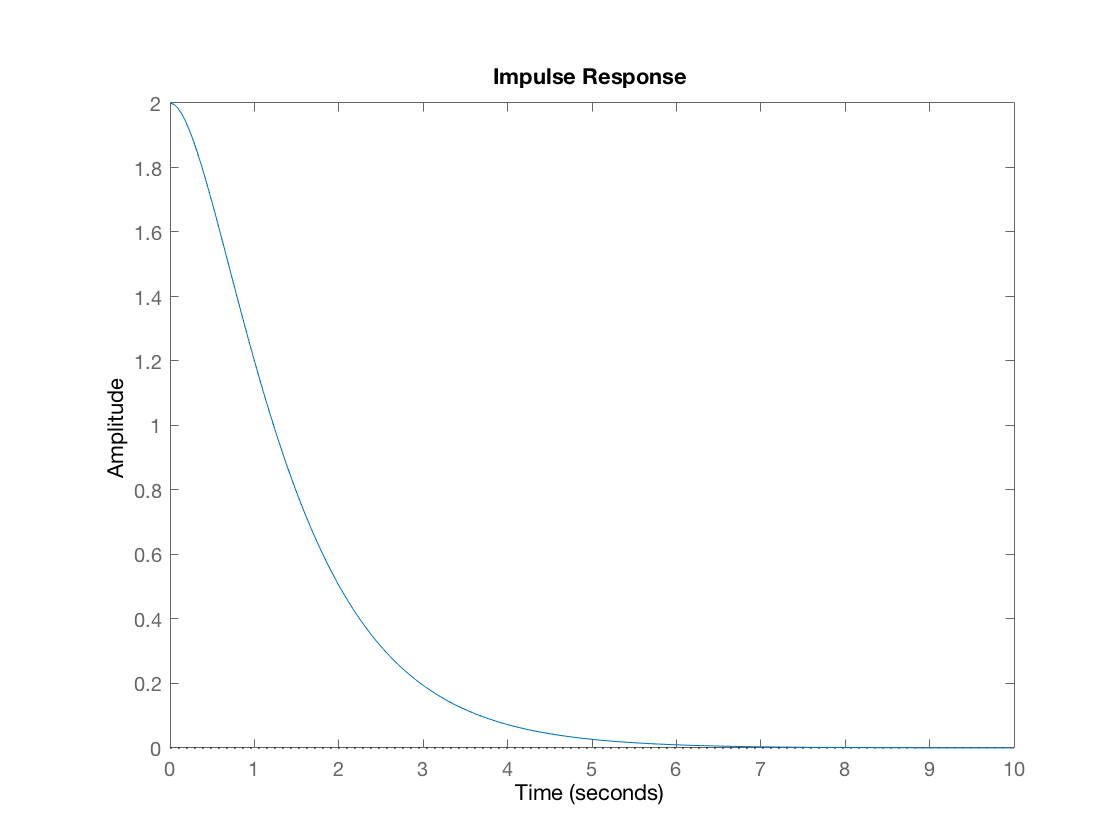

T = 10; % Final time value
figure;
impulse(H1, T)

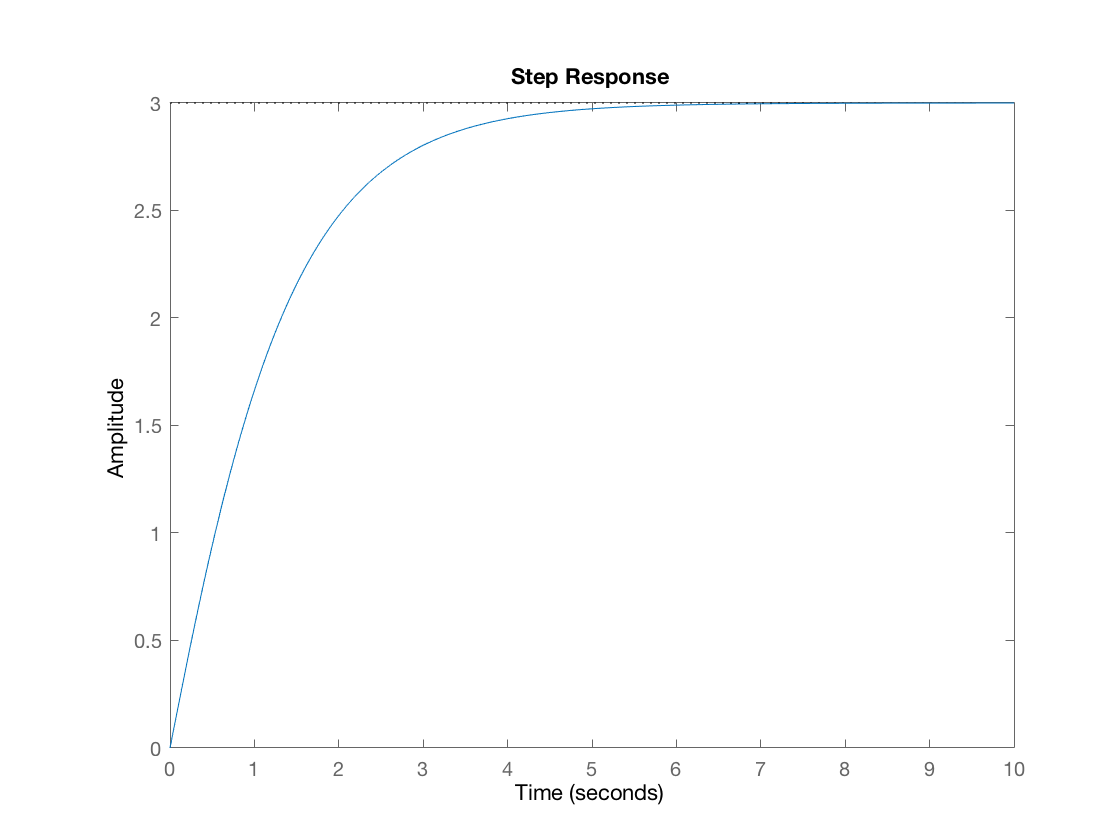

figure;
step(H1, T)

To find the poles and zeros of a transfer function, use `pole(system)` and `zero(systems)`. To plot the pole-zero plot, use `pzplot(system)`. For example, for the system defined above, the poles are

pole(H1)

ans =     -2
    -1


and the zeros are

zero(H1)

ans = -3

We can show the pole-zero plot using

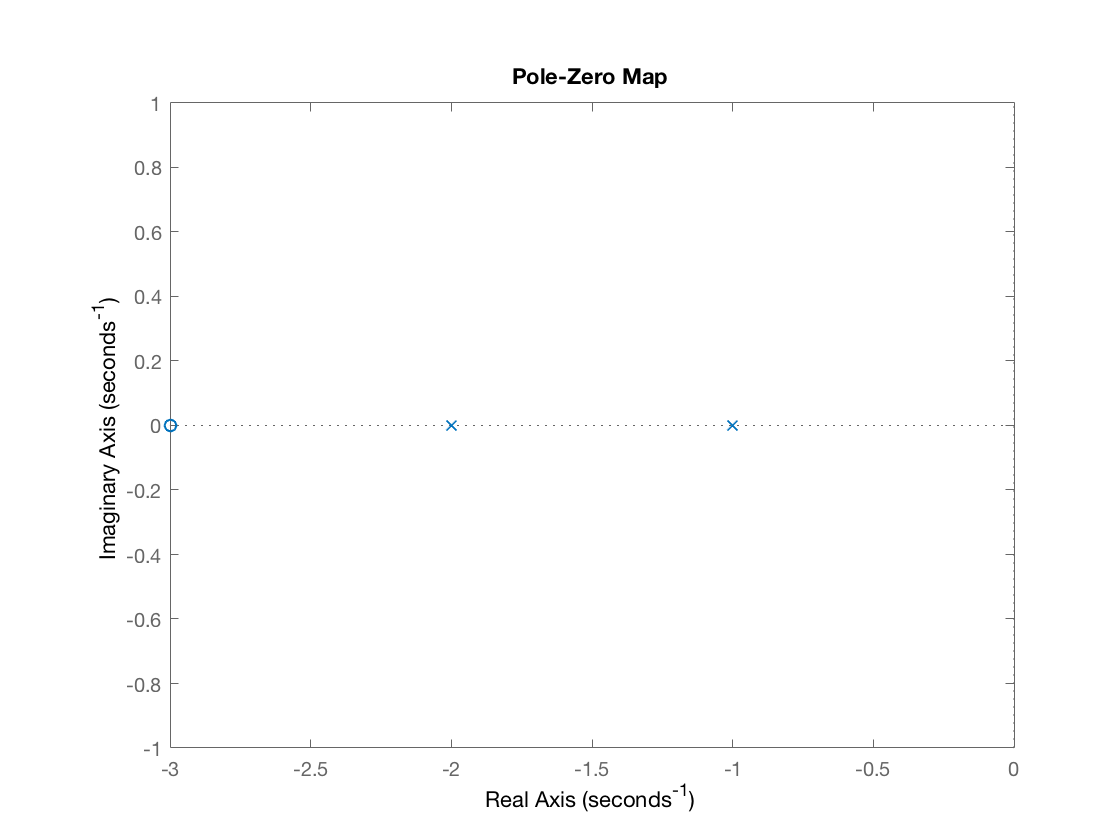

pzplot(H1)

## **Interconnecting systems**

To get the transfer function for two systems connected in feedback, use

H = feedback(H1, H2) % Feedback or closed-loop interconnection of systems


H =
 
     2 s^3 + 12 s^2 + 22 s + 12
  --------------------------------
  s^4 + 6 s^3 + 17 s^2 + 36 s + 40
 
Continuous-time transfer function.



Use `doc feedback` for more information.

## **3. System Response characteristics**

Consider the following step response of an unknown transfer function.

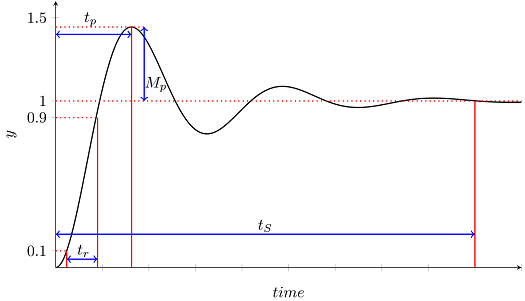

Depending on the location of the zeros and poles in a transfer function, it is possible to define a system response by the following characteristics:

- Rise time ($t_r$): is the time it takes the system to reach to rise from 10% to 90% of its final value.

- Peak time ($t_p$): is the time until the response hits its maximum overshoot.

- Overshoot ($M_p$): is the peak value of the step response of the system.

- Settling time ($t_s$): is the time for the response to settle within $\pm \Delta$ % of its final value.

It is possible to find these values in `MATLAB` given a transfer function. `stepinfo(sys)` computes the step-response characteristics for a dynamic system model. For example

stepinfo(H1)

ans = struct with fields:
        RiseTime: 2.4200
    SettlingTime: 4.1960
     SettlingMin: 2.7023
     SettlingMax: 2.9974
       Overshoot: 0
      Undershoot: 0
            Peak: 2.9974
        PeakTime: 7.3222


## *Question 1 (2 marks)*

For $\xi = \{0.25, 0.75, 1, 2\}$, plot the step response **(for 25 sec)** and identify the characteristics of the transient response of the following system


$$ G(s) = \displaystyle \frac{1}{s^2+2 \xi s + 1} $$


% For xi = 0.25
% Assign values to the coefficients
b0=1;
a0=1;
a10=.5;
a2=1;

% Define s symbolically in frequency domain
s=tf('s');

% Define the numerator & denominator
num=[b0];
den=[a2, a10, a0];

% Define the transfer function
H1=tf(num,den);


H1 =
 
         1
  ---------------
  s^2 + 0.5 s + 1
 
Continuous-time transfer function.



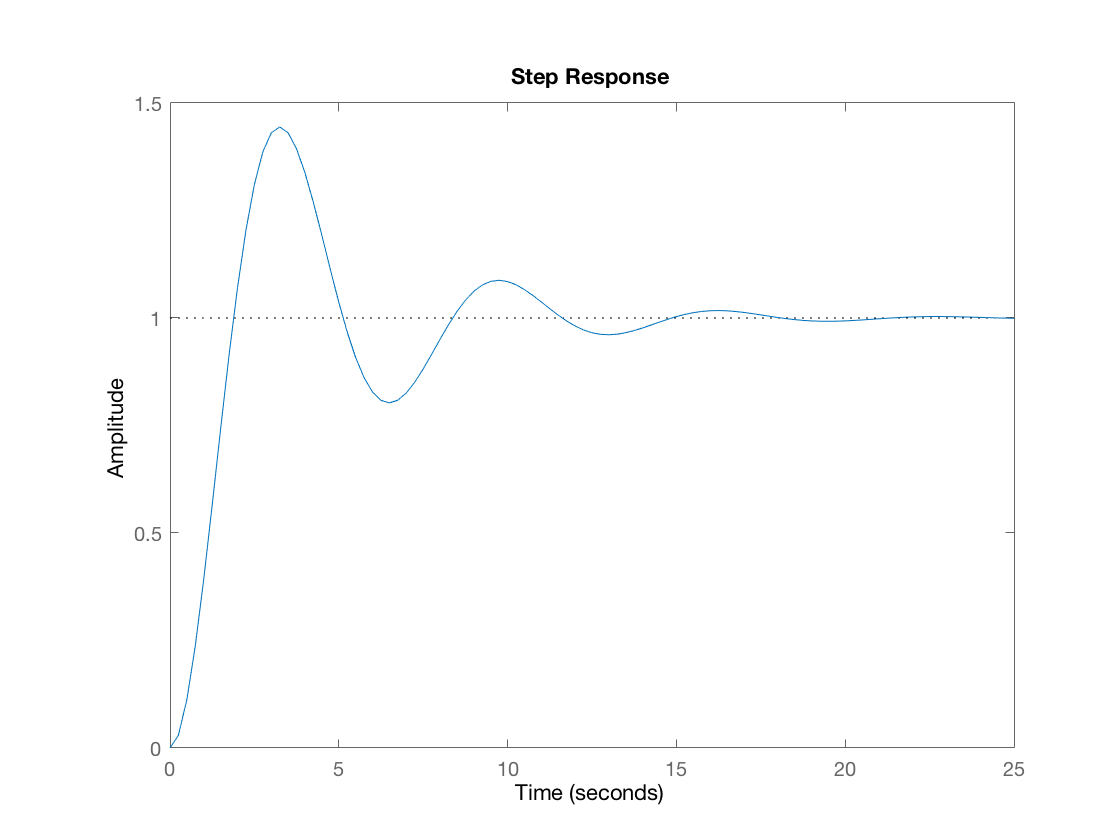


% Plot
T=25;
figure;
step(H1,T);

% For xi = 0.75
b0=1;
a0=1;
a11=1.5;
a2=1;
s=tf('s');

num=[b0];
den=[a2, a11, a0];
H2=tf(num,den);


H2 =
 
         1
  ---------------
  s^2 + 1.5 s + 1
 
Continuous-time transfer function.



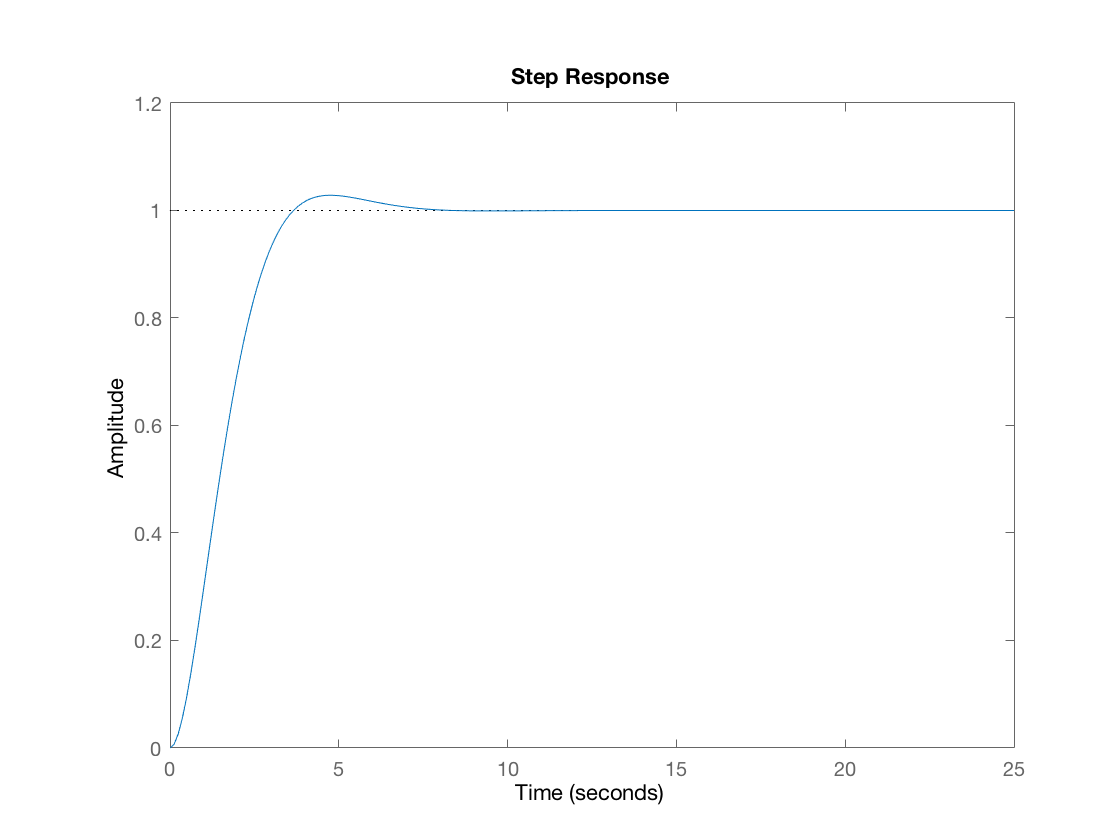


T=25;
figure;
step(H2,T);

% For xi = 1
b0=1;
a0=1;
a12=2;
a2=1;
s=tf('s');

num=[b0];
den=[a2, a12, a0];
H3=tf(num,den);


H3 =
 
        1
  -------------
  s^2 + 2 s + 1
 
Continuous-time transfer function.



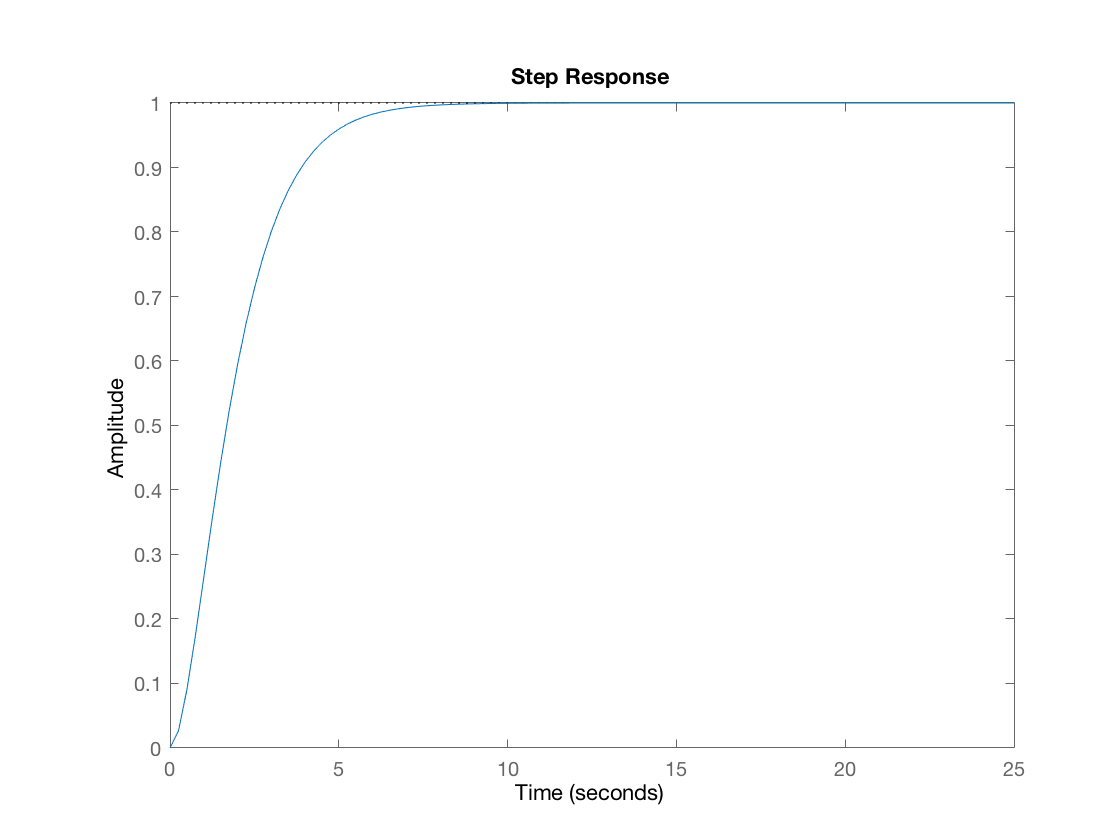


T=25;
figure;
step(H3,T);

% For xi = 2
b0=1;
a0=1;
a13=4;
a2=1;
s=tf('s');

num=[b0];
den=[a2, a13, a0];
H4=tf(num,den);


H4 =
 
        1
  -------------
  s^2 + 4 s + 1
 
Continuous-time transfer function.



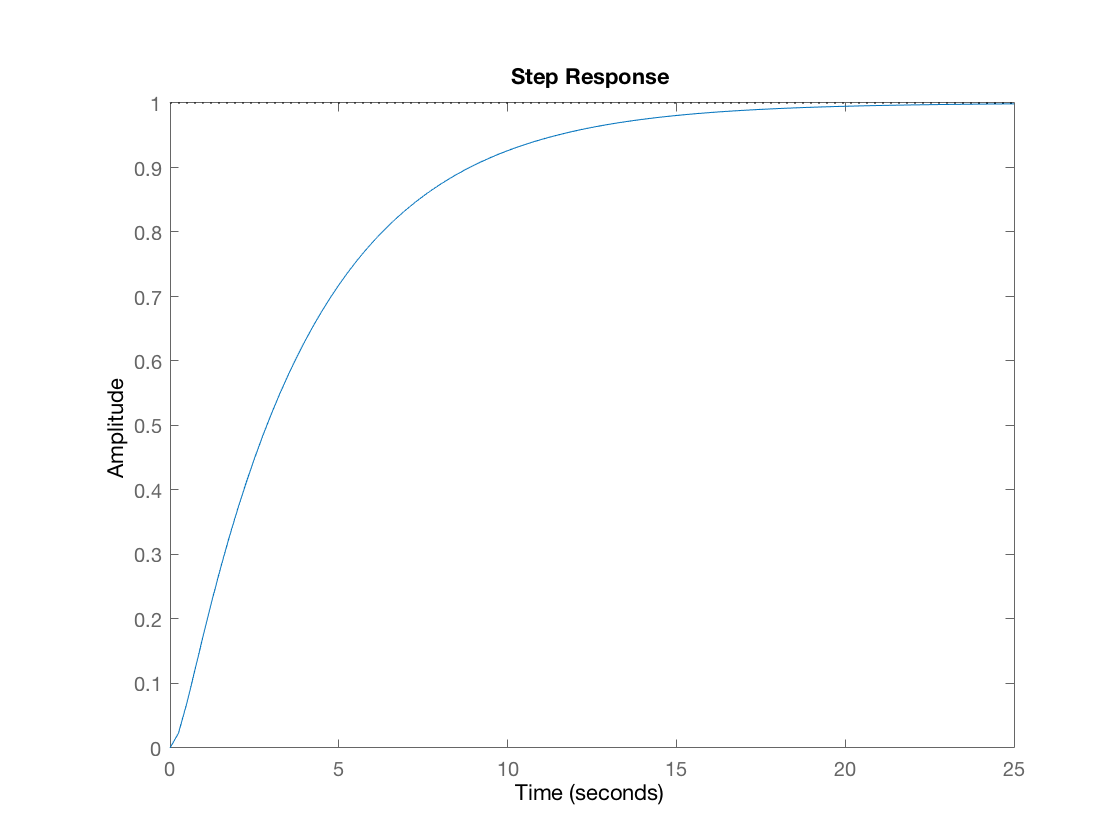


T=25;
figure;
step(H4,T);

## *Question 2 (4 marks)*

Consider the following open-loop unstable system.


$$ Q(s) = \displaystyle \frac{s+1}{s(s-1)(s+6)} $$


A constant gain $k$ (controller) is used to stabilize this system. For different values of $k \in \{10,\ 20,\ 50,\ 100\}$, plot the step response **(for 15 seconds)** of the closed-loop system and identify its characteristics using `stepinfo`.

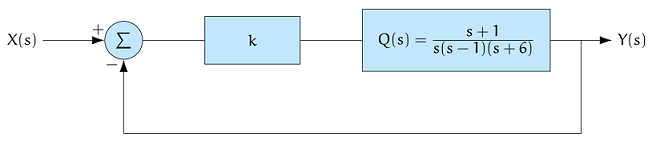

% Define the transfer function
z = [-1];
p = [0,1,-6];
Time = 15;

% k = 10
k0 = 10;
T0 = zpk(z, p, k0);


T0 =
 
    10 (s+1)
  -------------
  s (s-1) (s+6)
 
Continuous-time zero/pole/gain model.




Q0=feedback(T0, 1);


Q0 =
 
              10 (s+1)
  --------------------------------
  (s+4.603) (s^2 + 0.397s + 2.173)
 
Continuous-time zero/pole/gain model.



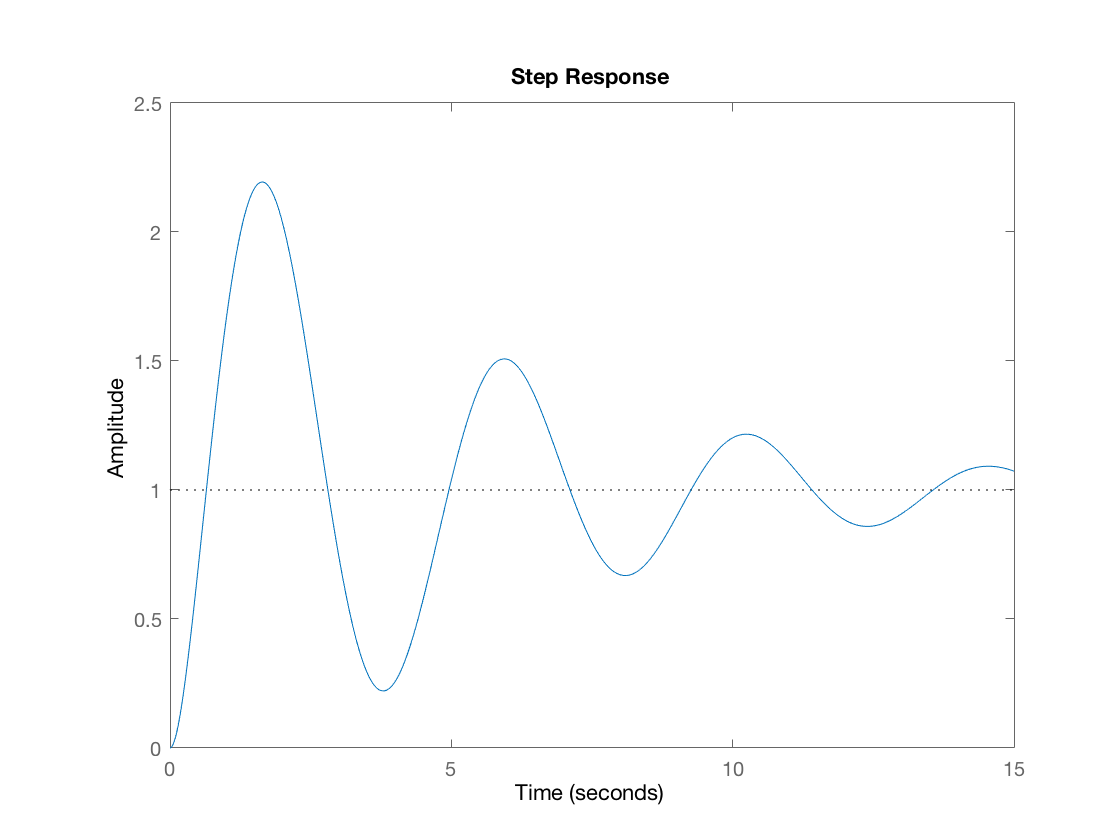

step(Q0, Time);

stepinfo(Q0);

ans = struct with fields:
        RiseTime: 0.4424
    SettlingTime: 21.2506
     SettlingMin: 0.2212
     SettlingMax: 2.1939
       Overshoot: 119.3930
      Undershoot: 0
            Peak: 2.1939
        PeakTime: 1.6408


% k = 20
k1 = 20;
T1 = zpk(z, p, k1);


T1 =
 
    20 (s+1)
  -------------
  s (s-1) (s+6)
 
Continuous-time zero/pole/gain model.




Q1=feedback(T1, 1);


Q1 =
 
              20 (s+1)
  --------------------------------
  (s+2.579) (s^2 + 2.421s + 7.756)
 
Continuous-time zero/pole/gain model.



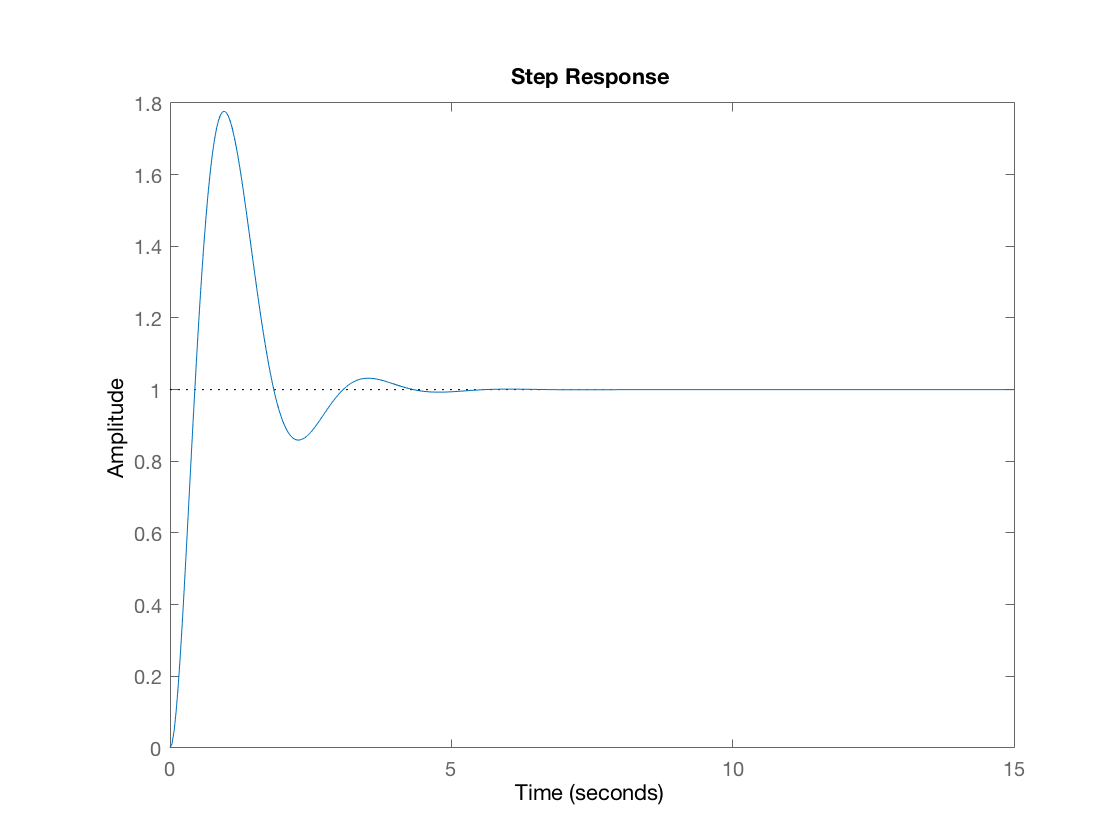

step(Q1, Time);

stepinfo(Q1);

ans = struct with fields:
        RiseTime: 0.2989
    SettlingTime: 3.8974
     SettlingMin: 0.8592
     SettlingMax: 1.7772
       Overshoot: 77.7158
      Undershoot: 0
            Peak: 1.7772
        PeakTime: 0.9644


% k = 50
k2 = 50;
T2 = zpk(z, p, k2);


T2 =
 
    50 (s+1)
  -------------
  s (s-1) (s+6)
 
Continuous-time zero/pole/gain model.




Q2=feedback(T2, 1);


Q2 =
 
              50 (s+1)
  --------------------------------
  (s+1.274) (s^2 + 3.726s + 39.25)
 
Continuous-time zero/pole/gain model.



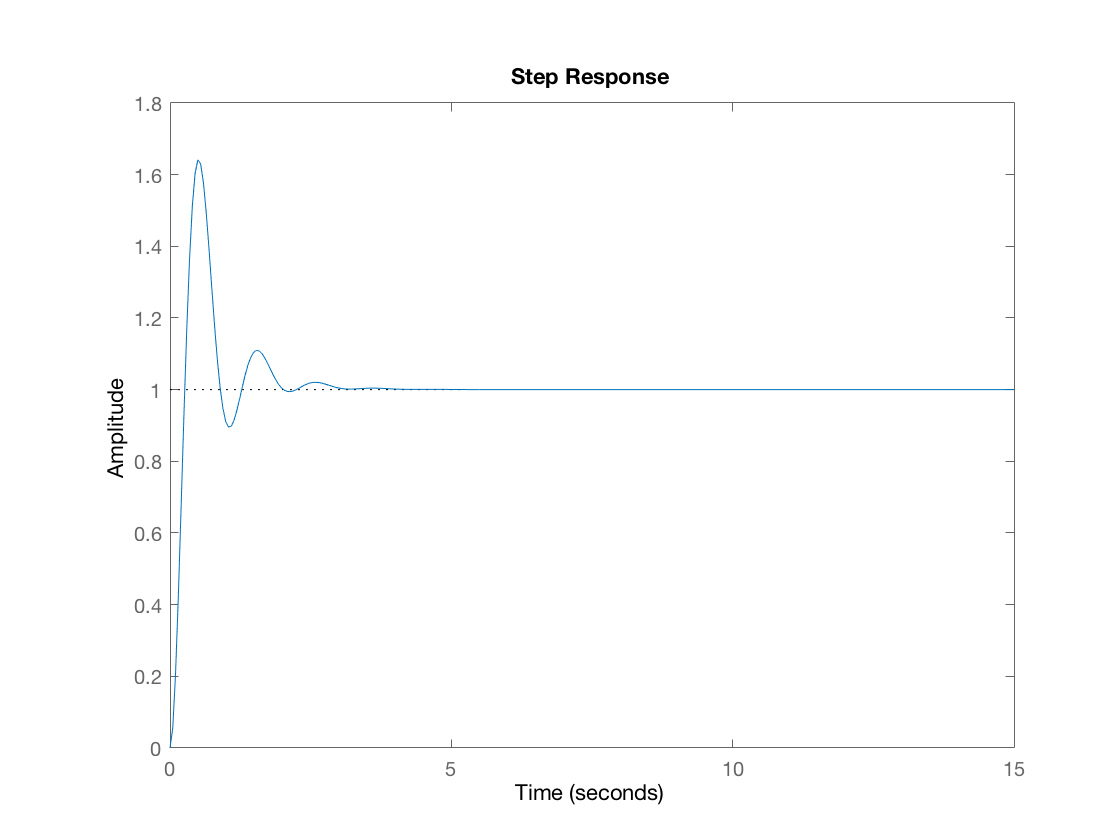

step(Q2, Time);

stepinfo(Q2);

ans = struct with fields:
        RiseTime: 0.1767
    SettlingTime: 2.6377
     SettlingMin: 0.8948
     SettlingMax: 1.6430
       Overshoot: 64.3033
      Undershoot: 0
            Peak: 1.6430
        PeakTime: 0.5062


% k = 100
k3 = 100;
T3 = zpk(z, p, k3);


T3 =
 
    100 (s+1)
  -------------
  s (s-1) (s+6)
 
Continuous-time zero/pole/gain model.




Q3=feedback(T3, 1);


Q3 =
 
             100 (s+1)
  --------------------------------
  (s+1.115) (s^2 + 3.885s + 89.67)
 
Continuous-time zero/pole/gain model.



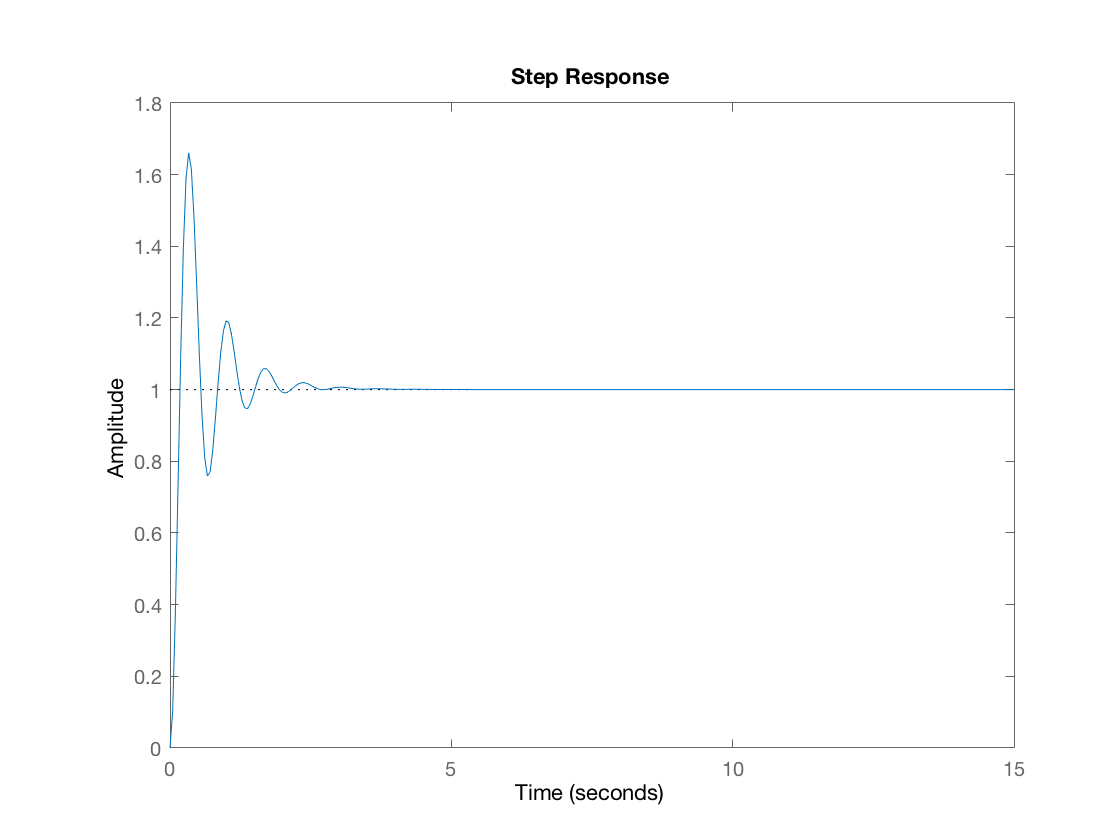

step(Q3, Time);

stepinfo(Q3);

ans = struct with fields:
        RiseTime: 0.1190
    SettlingTime: 1.8674
     SettlingMin: 0.7606
     SettlingMax: 1.6607
       Overshoot: 66.0662
      Undershoot: 0
            Peak: 1.6607
        PeakTime: 0.3303


## *Question 3 (4 marks)*

Consider the closed-loop transfer function in Question 2.


$$ T(s) = \displaystyle \frac{k Q(s)}{1 + k Q(s)} $$


We would like to approximate this system to a second order system of the form:


$$ G(s) = \displaystyle
\frac{\displaystyle\frac{k}{|p_3|}(s-z_1)}{(s-p_1)(s-p_2)} $$


- For $k = \{10,\ 20\}$, find $p_1$, $p_2$ and $p_3$, where $p_1$ and $p_2$ are the dominant poles (i.e., poles with the smallest absolute real values) and $p_3$ is the ineffective pole(i.e., the pole with the largest absolute real value).

- For $k = \{10,\ 20\}$, plot the step response of the new second order system for **15 sec** and identify its characteristics using `stepinfo`.

- For $k = \{10,\ 20\}$, compare the step response with those obtained in Question 2. What do you observe?

- 1)

% Find the poles of the two transfer functions
pole(Q0);

ans =   -4.6030 + 0.0000i
  -0.1985 + 1.4605i
  -0.1985 - 1.4605i


pole(Q1);

ans =   -1.2107 + 2.5081i
  -1.2107 - 2.5081i
  -2.5786 + 0.0000i


% The poles below represent the ineffective pole (ie the pole with the largest absolute value
% For k = 10 and k=20 respectively

p30= -4.603;
p31= -2.5786;



% Transfer functions with dominant poles
b01=10;
b11=10;
a01=2.173;
a15=.397;
a21=1;
s=tf('s');

num=[b11, b01];
den=[a2, a15, a01];
G1=tf(num,den);
G10=((10/abs(p30))*(s+1))/(s^2+0.397*s+2.173);

b02=20;
b12=20;
a02=7.756;
a16=2.421;
a22=1;
s=tf('s');

num=[b12, b02];
den=[a22, a16, a02];
G2=tf(num,den);
G12=((20/abs(p31))*(s+1))/(s^2+2.421*s+7.756);

% k = 10
pole(G1);

ans =   -0.1985 + 1.4607i
  -0.1985 - 1.4607i


% k = 20
pole(G2);

ans =   -1.2105 + 2.5081i
  -1.2105 - 2.5081i


- 2)

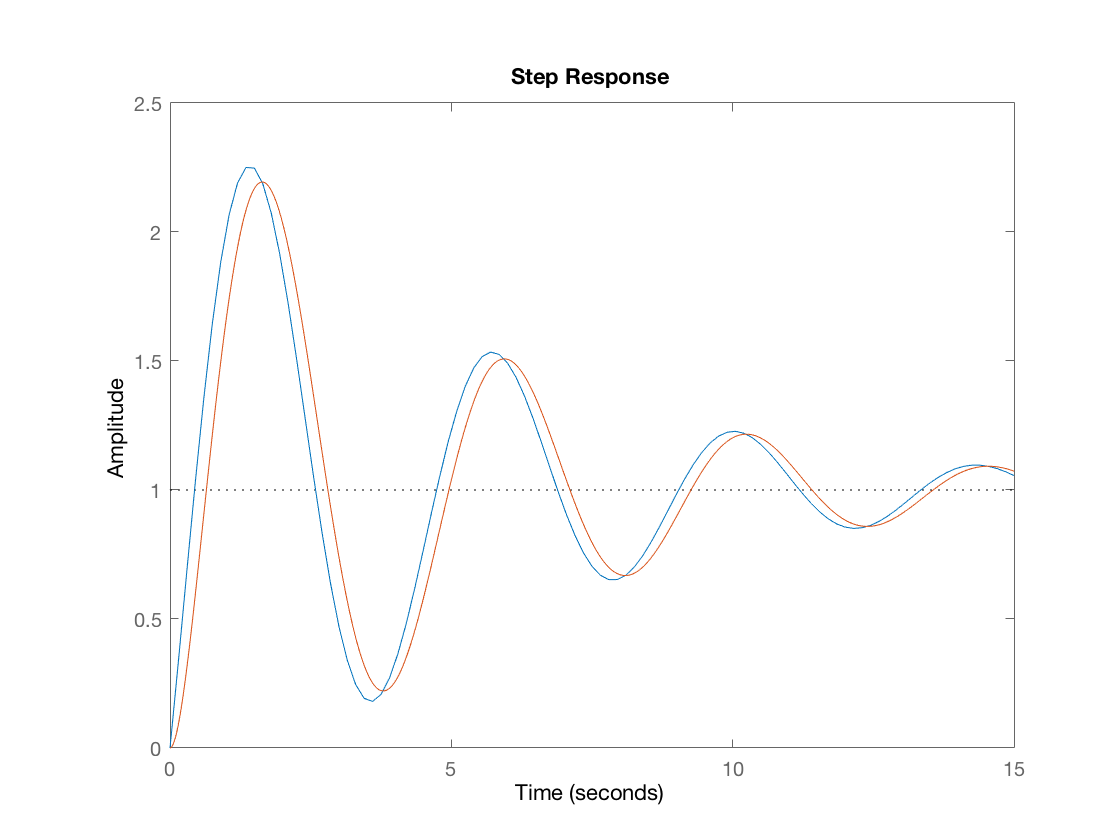

% k = 10
figure;
step(G10,Time);
hold on 
step(Q0,Time);

stepinfo(G1);

ans = struct with fields:
        RiseTime: 0.3486
    SettlingTime: 21.0216
     SettlingMin: 0.8385
     SettlingMax: 10.3542
       Overshoot: 124.9968
      Undershoot: 0
            Peak: 10.3542
        PeakTime: 1.4918


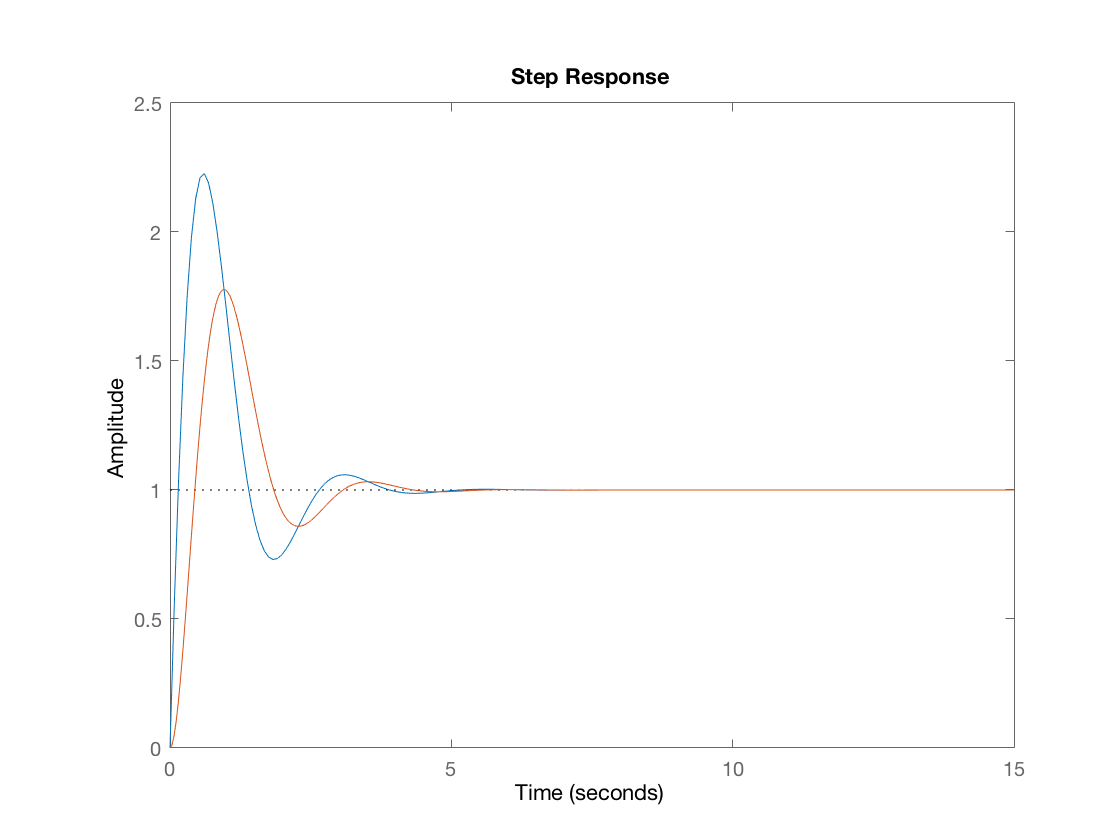

% k = 20
figure;
step(G12,Time);
hold on 
step(Q1,Time);

stepinfo(G2);

ans = struct with fields:
        RiseTime: 0.1163
    SettlingTime: 3.6017
     SettlingMin: 1.8844
     SettlingMax: 5.7421
       Overshoot: 122.6770
      Undershoot: 0
            Peak: 5.7421
        PeakTime: 0.6087


- 3)

% k = 10


% k = 20
%

% [Answer here]
% As can be seen from observing the graphs, when removing the pole with the 
% highest absolute value, it has a significant affect on the step response,
% To begin with, the amplitude of our graph in Question 3 increases as compared
% To the graph in Question 2, by a factor of approximately three. In addition
% to this, it can be seen that the time scale has shifted, in which the graph
% in Question 3 stabilizes earlier than the graph in Question 2.
% Thus, it can be seen that deleting the weakest pole results in 
% a lower RiseTime, SettlingTime, Peaktime, and SettlingMin and hence
% improves the system response rate